# Calculation of local relative rate (LRR) from dynamic time warping

This script describes the concept of **local relative rate** **(LRR) **and shows how it is calculated from the warping curve obtained from dynamic time-warping of a set of signals.

%REQUIRED: this script should be run with its parent directory 
% and all of the parent's subdirectories on your path:
addpath(genpath('..')) 

%REQUIRED: the toolbox DTWm (https://github.com/tilsen/DTWm.git)
if ~contains(path,'DTWm')
    fprintf('toolbox DTWm required\n'); return;
end

#### Input: a set of signals. Linear growth and decay

Here is a set of three signals for which we will calculate local relative rate. Each of these is triangular function, but the periods differ. The parameter $r$ can be thought of as a constant growth/decay rate of a process which generates these signals.

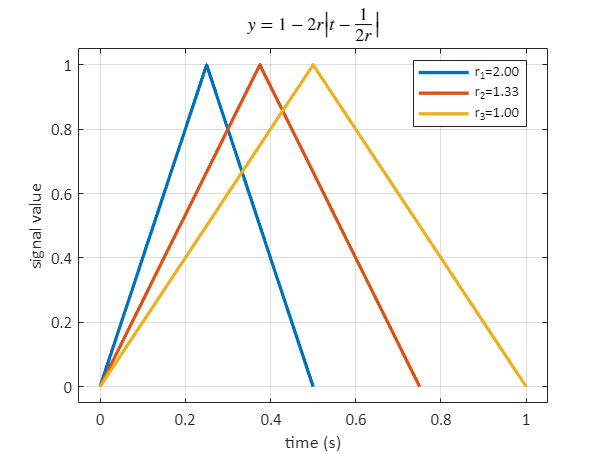

%Note: the dtwm toolbox (https://github.com/tilsen/DTWm.git) must be on your path

S = test_signals('lin_rate_var',{'n',3});
plot_signals(S);

Note that only three signals are use here to simplify the exposition, but in general we would typically use a larger set of signals. The sampling rate of all three signals is $1000$ Hz.

#### Assumed properties of the set of signals

The following must obtain in order for the method of local relative rate calculation to make sense:

- The set must contain two or more signals. The local rates that are calculated are always *relative* to some other signal(s). The method does not provide an absolute local rate of a signal.

- The signals should represent the same underlying generation mechanism, or similar generation mechanisms. The signals should therefore have similar shapes. This is a loose constraint and it is hard to specify how dissimilar the signal shapes can be before the method breaks down. 

- Although not absolutely necessary, the sampling rate should be relatively high compared to the highest frequency components of the signals.

- All signals must be sampled at the same rate, and the sampling rate should be constant. If this is not the case, it is necessary to resample/interpolate.

#### Dynamic time warping

First, we calculate the warping curves from pairwise dynamic time warping between all signals using the toolbox function `dtwm.m `(Note that this function is described in detail in `dtwm_examples.mlx`).

for a=1:length(S.X)
    for b=1:length(S.X)
        [wcurves{a,b},dists(a,b),dtwinfo(a,b)] = dtwm(S.X{a},S.X{b});
    end
end

The first output of `dtwm` is the ***warping curve*** or ***warping path***, or as we prefer to call it here, the ***time index mapping*** of the dynamic time warping. The mapping is an ordered set of relations between time indices of the two signals, which we will refer to as the **target **and the **comparison**. In traditional terms these signals are often called the "reference" and the "test", but for the purposes of local relative rate analyses, "target" and "comparison" are more sensible. Only the first ten relations in the mapping are shown below:

warping_curve_first10 = wcurves{1,2}(:,1:10)

warping_curve_first10 =      1     2     2     3     4     4     5     6     6     7
     1     2     3     4     5     6     7     8     9    10


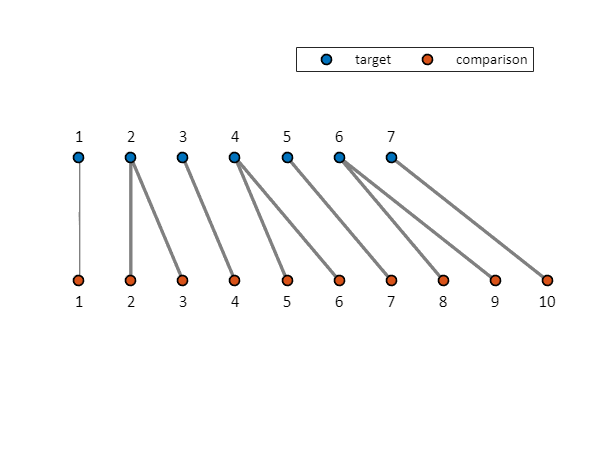


fig; h = plot_time_map(warping_curve_first10(:,1:10));
mapping_legend(h,{'target' 'comparison'});

#### Local cost matrix

This is the local cost matrix and optimal warping path for the warping of the first and second signals in the set.

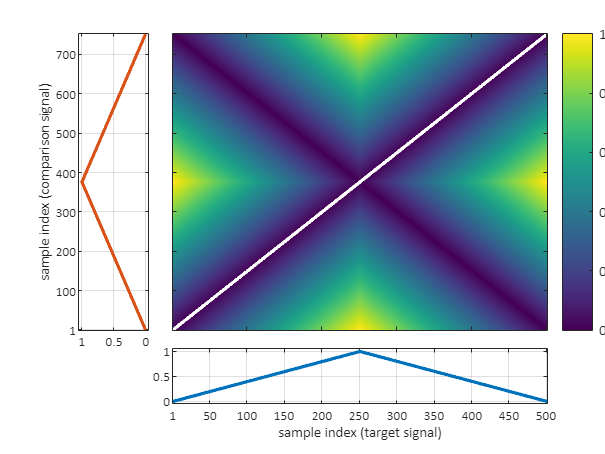

fig;
h = plot_dtw_matrix(dtwinfo(1,2),S.X{1},S.X{2});

h.xlabs1.String = [h.xlabs1.String ' (target signal)'];
h.ylabs2.String = [h.ylabs2.String ' (comparison signal)'];

The phrase "warping path" evokes the idea that the time indices of the map are spatial dimensions and the local cost matrix is an elevation that depends on spatial location. The optimal "path" through the local cost matrix is the one that minimizes the total elevation on the path.

#### Global slope

Notice that the optimal warping path (a mapping between signal time indices) looks like a smooth, straight line in this example, but its slope is not equal to $1$.0. The "global slope" of the line in this case is the ratio of the* range of comparison (test) signal indices* to the *range of target (reference) signal indices*, i.e.

global slope = $\frac{751-1}{501-1}=\frac{750}{500}=1.5$

global_slope = (length(S.X{2})-1)/(length(S.X{1})-1)

global_slope = 1.5000

#### Local slope

If we imagine zooming in on smaller and smaller portions of the warping map, it might seem that the slope of the line will continue to be $1.5$--after all, it looks like a smooth line in the figure.

But, the notion of the slope breaks down as we approach the scale of individual sample indices, because...

#### Functions have slopes, maps do not

In general, functions have slopes, but mappings do not. The dtw mapping can have one-to-many and many-to-one relations: the sample index of one signal in a DTW map can be associated with more than one time point in the other, and vice versa. In contrast, functions map each value of the domain (horizontal coordinate) to one value of the co-domain (vertical coordinate).

In fact, the mapping we described as "straight line" with a global slope of $1.5$ above is not a straight line, and not a function. This can be seen by zooming in on a small region of the mapping:

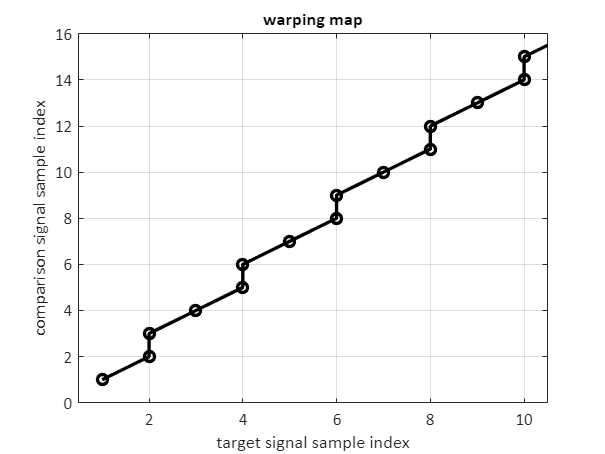

fig; plot(dtwinfo(1,2).index1s,dtwinfo(1,2).index2s,'ko-');
format_plot('example_zoom');

For some indices of the target signal (blue), those indices are mapped to multiple values of the comparison signal (orange).

#### Toy many-to-many example

Here is a simple example of signals whose warping maps have one-to-many relations:

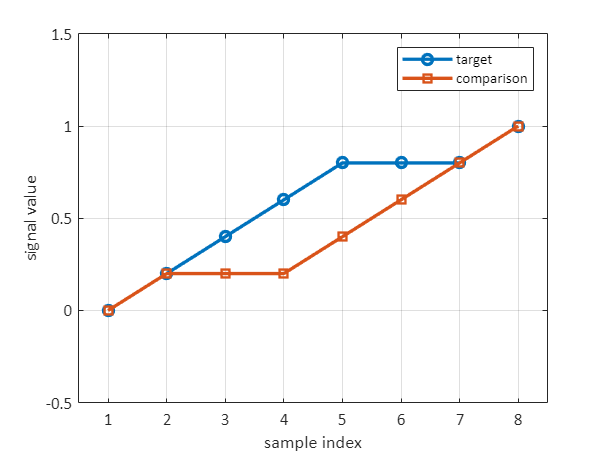

mm = test_signals('many_to_many_example');
plot_toy_example_signals(mm);

Calculate and plot the dynamic warping curve:

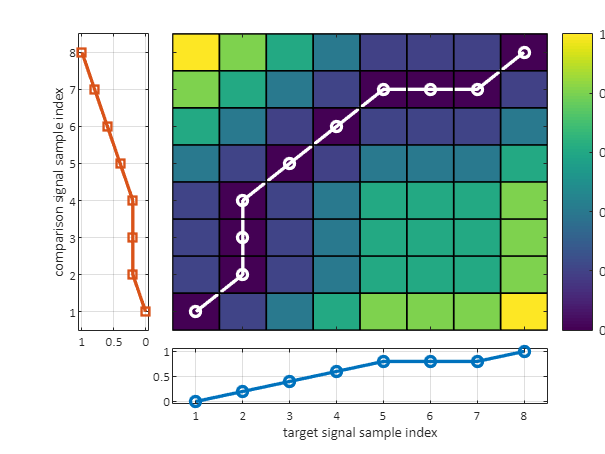

[ww_map,ww_dist,ww_info] = dtwm(mm.X{1},mm.X{2});

fig;
h = plot_dtw_matrix(ww_info,mm.X{1},mm.X{2});
format_plot('many_to_many_map',h);

In this example, there are both one-to-many and many-to-one mappings: sample 2 of the target signal (blue) maps to samples 2, 3, and 4 of the comparison (orange), and sample 7 of the comparison maps to samples 5, 6, and 7 of the target.

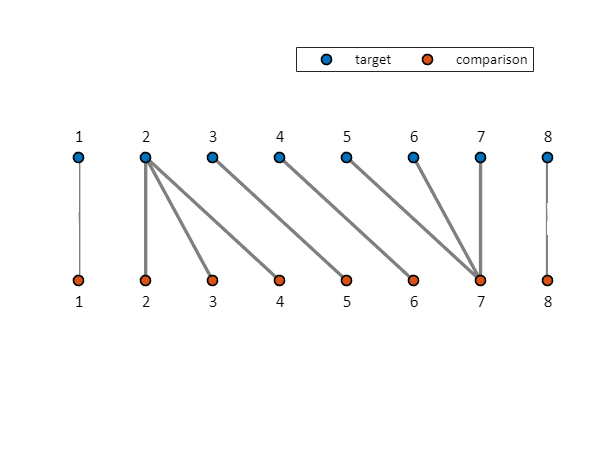

fig; 
h = plot_time_map(ww_map);
mapping_legend(h,{'target' 'comparison'});

#### Definitions of local slope

For a function defined at a set of uniformly spaced discrete points, we can define the slope at any point in the domain of the function using finite differences between values. Consider the slope at sample index $5$. There are three sensible ways to define the slope:

- Backwards:     $\frac{f(x)-f(x-\Delta x)}{\Delta x}$

- Forwards:     $\frac{f(x+\Delta x)-f(x)}{\Delta x}$    

- Central:       $\frac{f(x+\Delta x)-f(x-\Delta x)}{2\Delta x}$    = average of backwards and forwards differences.

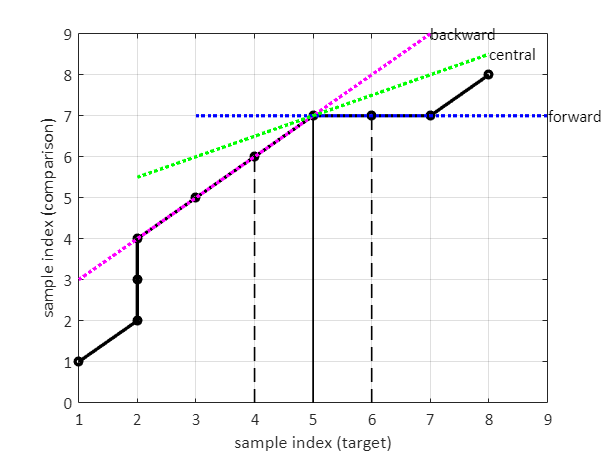

slope_defs(ww_map);

The central difference is preferable because the forward/backward options ignore changes in the backward/foward directions of time, respectively. Central difference weights forward and backward differences equally. We will focus on this method from here on, but the points below can be applied to forwards or backwards differences as well. Note that with central differencing, we determine the slopes at the first and last points in the domain of the function with forwards and backwards differencing.

At sample index $2$ of the target signal, where the mapping is one-to-many, we cannot simply apply any of the above definitions because there are multiple time indices of the comparison signal that are mapped to this time index of the target. Consider the slope at sample index $2$, what is the "slope" of the warping curve at this time point?

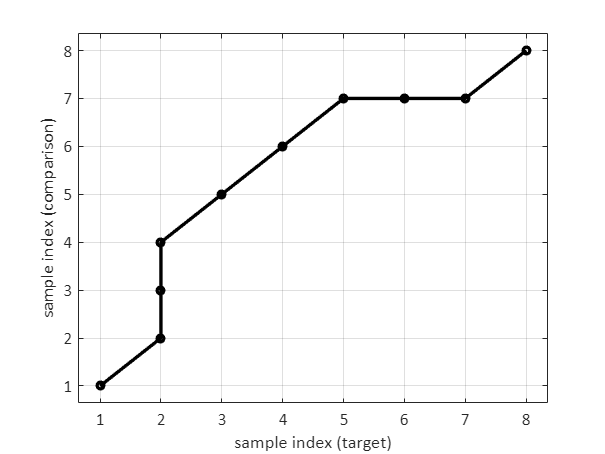

fig;
plot(ww_map(1,:),ww_map(2,:),'ko-','markersize',4); hold on;
xlabel('sample index (target)'); 
ylabel('sample index (comparison)'); 
format_axes;

It turns out that if choose just one of any of three comparison signal indices associated with target signal index $2$, we get the same result. Even though the backward and forward differences are different, their average remains the same:

m = ww_map;

backward_diff = @(x,y)(y(2)-y(1))/(x(2)-x(1));
forward_diff = @(x,y)(y(3)-y(2))/(x(3)-x(2));
central_diff = @(x,y)(backward_diff(x,y)+forward_diff(x,y))/2;

IXS = {[1 2 5],[1 3 5],[1 4 5]};

for i=1:length(IXS)
    slopes(i,:) = [backward_diff(m(1,IXS{i}),m(2,IXS{i}))
    forward_diff(m(1,IXS{i}),m(2,IXS{i}))
    central_diff(m(1,IXS{i}),m(2,IXS{i}))];
end

disp(array2table(slopes,...
    'RowNames',{'choose: f(2)=2','choose: f(2)=3','choose: f(2)=4'},...
    'VariableNames',{'backward' 'forward' 'central'}))

                      backward    forward    central
                      ________    _______    _______

    choose: f(2)=2       1           3          2   
    choose: f(2)=3       2           2          2   
    choose: f(2)=4       3           1          2   



#### Local linear regression

Linear regression is a more general way to get the local slope of a warping curve, but its results are equivalent to the "just choose one value" approach above. It doesn't matter if we provide multiple relations for a given index of the target signal:

X = [ones(5,1) m(1,1:5)']

X =      1     1
     1     2
     1     2
     1     2
     1     3


Y = m(2,1:5)'

Y =      1
     2
     3
     4
     5


coeffs = regress(Y,X);
slope = coeffs(2)

slope = 2

or in matrix form:

coeffs = (X'*X)\(X'*Y);  %eq. to inv(X'*X)*(X'*Y)
slope = coeffs(2)

slope = 2.0000

So, by performing a regression with all of the time-index mapping relations associated with target time index $2$ and its nearest neighbors, we obtained a slope that is equivalent to the central difference for any of three choices of the comparison signal index that maps to target signal index $2$.

The fact that the local slope at target signal time index #$2$ has a value of $2.0$ means that the comparison signal time index is increasing by $2$ for a change of $1$ in the target signal time index. This makes sense since we can see that $m(1)=1$ and $m(3)=5$.

#### Parameterization of locality

Why use linear regression? The local slope that we calculated above is as local as possible. But what if the warping curve is very wiggly at the most local scale? In that case, we might want to obtain a smoother representation of slope based upon more than just a single target signal index and its nearest neighbors. To do this we simply include a larger window of the warping curve in the regression:

window_sizes = [3 5 7 9];

for i=1:length(window_sizes)
    local_slopes{i} = lrr(m,'winsize',window_sizes(i),'window','rectangular');
end

The bottom plot below shows the local slope at each target index, for odd window sizes from 3 to 9. The window size refers to the range of target sample indices included in the calculation of local slopes.

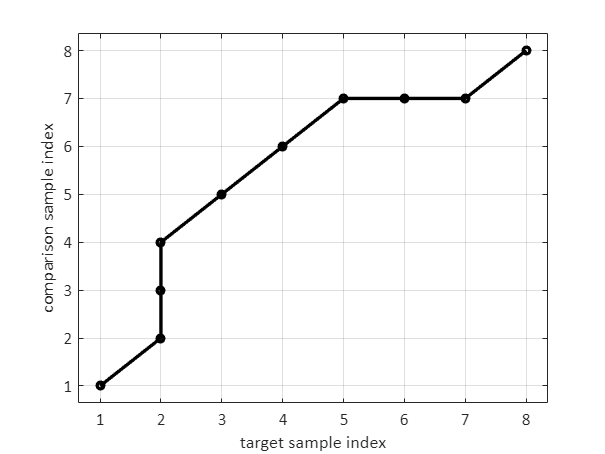

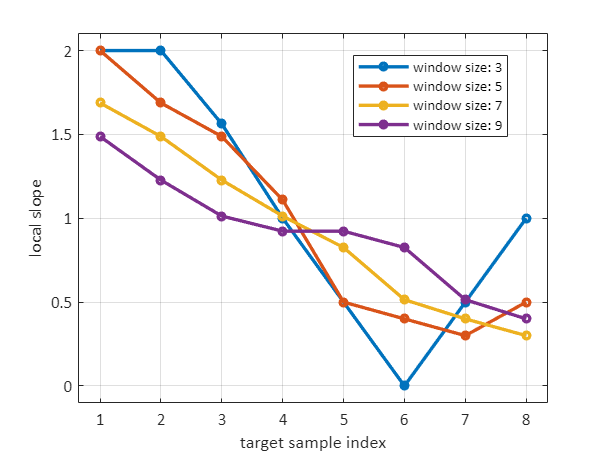

locality_comparison(m,local_slopes,window_sizes);

#### Weighted local linear regression

The local linear regressions shown above used a rectangular window function, where all points of the warping curve in each window were given equal weight. To get more precise slope estimates we can weight the points of the curve according to their distance from the central point. Two such functions are shown below,  where $t_c$ is the central point of the regression. For the triangular function, $T$ is the window size, and for the Gaussian function, $T$ is the standard deviation:

- triangular window function: $w(t)=\max\left(0,1-\frac{|t-t_c|}{T/2}\right)$. This is the default of `tempdist_local_slope.m`.

- Gaussian window function: $w(t)=\exp\left(-\frac{(t-t_c)^2}{2(T/2)^2}\right)$

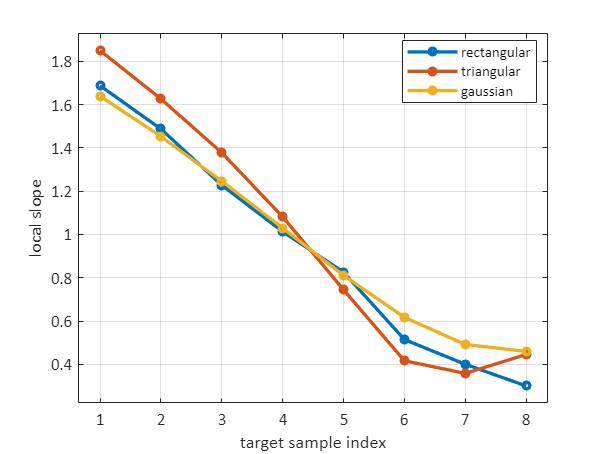

windows = {'rectangular','triangular','gaussian'};
winsizes = [7 7 3.5];

for i=1:length(windows)
    local_slopes_windowed{i} = lrr(m,'winsize',winsizes(i),'window',windows{i});
end

windows_comparison(local_slopes_windowed,windows);

#### Asymmetry of slope and local relative rate

An important point to emphasize about the notion of the slope of the warping curve is that we impose an asymmetric conception of the signals: the local slope is the local rate of change of the comparison signal time indices with respect to change in the target signal time index.

In the example above, and in general, where the local slope is $>1$, it implies that the comparison signal must be sped up to align it with the target signal (the counterfactual/alignment interpreation). Equivalently, this implies that target signal was advancing more quickly than the comparison (the actual/local relative rate interpretation). 

Conversely, where the local slope is $<1$, the comparison must be slowed down to align it to the target. Equivalently, the target was advancing more slowly than the comparison. Our manuscript further explains the relations between the counterfactual/alignment and actual/local relative rate interpretations of the local slope.

These interpretations can be confirmed by looking at the original signals:

mm = test_signals('many_to_many_example');
plot_toy_example_signals(mm);

Early in the toy example, the target (blue) advances more quickly than the comparison (orange)--the local slope/local relative rate is $>1$. Later in the example, the target advances more slowly than the comparison--the local slope/local relative rate is $<1$.

Here is an example of three constant rate growth-decay signals with rates that are equally spaced on a logarithmic scale, i.e. the ratios of the growth rates are identical:

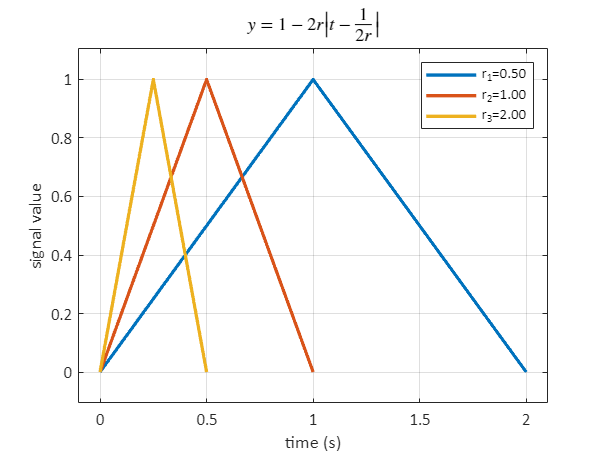

S = test_signals('lin_rate_var2');
ph = plot_signals(S);
format_plot('example_set',S,ph);

Calculate all local relative rates:

loc_rates = {};
for a=1:length(S.X)
    for b=1:length(S.X)
        [wcurves{a,b},dists(a,b),dtwinfo(a,b)] = dtwm(S.X{a},S.X{b});
        loc_rates{a,b} = lrr(wcurves{a,b});
    end
end

Often we want to analyze variation in the local rate of one signal--a *target* signal--relative to all other signals in our set of signals--the *comparison* signals. To do this, we want the target signal to be the domain (horizontal coordiante) in each slope calculation. This reason that we want the target signal to be the domain is that this ensures that the local relative rate functions are defined at the same "points in time"--the sample indices of the target signal.

For example, here are the local relative rates when the first signal is the target signal:

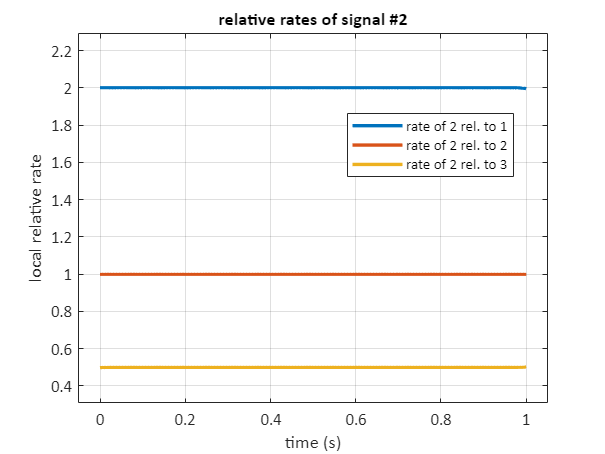

signal_num = 2;

plot_relative_rates(S,loc_rates,signal_num);

Notice that the rate of signal #2 relative to itself is 1. Furthermore, signal #2 (growth rate $1.0$) advances at a rate of $2.0$ relative to signal #1 (growth rate $1$), and at a rate of $0.5$ relative to signal #3 (growth rate $2.0$). The local relative rate values are identical to the ratios of the growth rate parameters that were used to define the signals:

growth_rates = S.frq

growth_rates =     0.5000    1.0000    2.0000


relative_growth_rates = triu(growth_rates'./growth_rates)

relative_growth_rates =     1.0000    0.5000    0.2500
         0    1.0000    0.5000
         0         0    1.0000


#### Average local relative rate

To characterize the typical local relative rate of a target signal relative to all other signals in a corpus (the comparisons), we simply average over the pairwise relative rates in which the target was the horizontal component of the slope calculation. The geometric mean is preferable because we are dealing with ratios of rates (see manuscript for further discussion of this point).

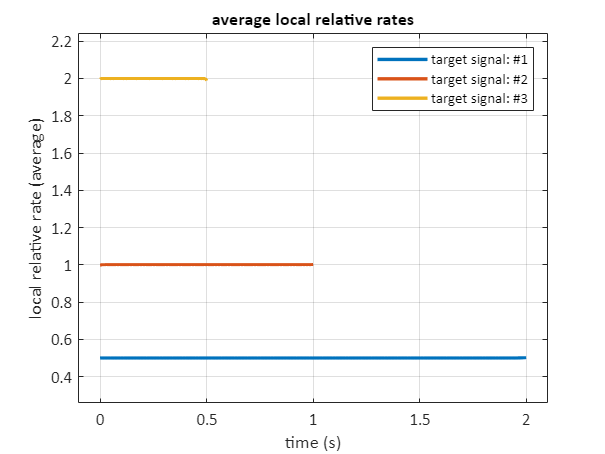

fig; plot_average_local_rates(S,loc_rates);

Notice that the length of each local relative rate time series matches the original length of the target signal. Also, the growth rates in this example were designed such that rate of signal #2 is the geometric average of the rates of the signals #1 and #3. This is reflected by the fact that the average local relative rate is $1.0$ for signal #2.

Intuitively, the average local relative rate  of a given target signal represents, for each point of time in the target signal, how much that signal is sped up ($>1$) or slowed down ($<1$) relative to all of the other signals in the set. 

An alternative to averaging over the other signals in the set is to simply use a fixed control signal, in which case a the local relative rate would be calculated between each target signal and the fixed control signal.

Note that in general the geometric average of the local relative rate for a given target in a set of signals is not equivalent to the local relative rate of a target signal warped to the average of all other signals in the set.

#### Another example with a constant rate difference: cosines of varying frequency

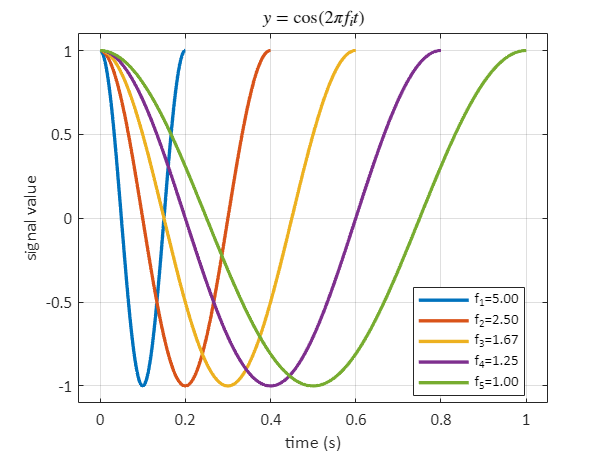

S = test_signals('cos_freq_var');
plot_signals(S);

DTW and local rate calculation:

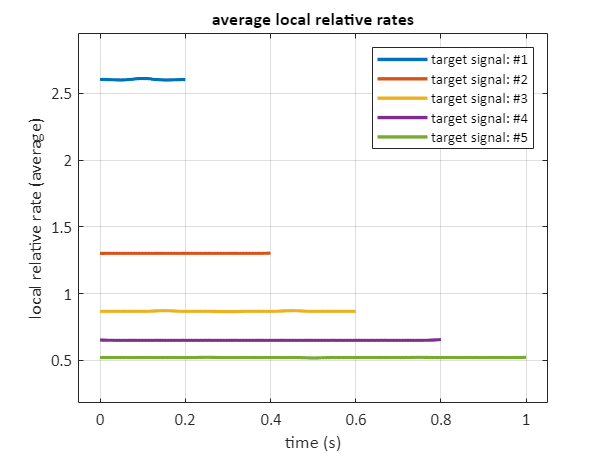

winsize = round(0.1/S.dt); %window size of 0.05 s

for a=1:length(S.X)
    for b=1:length(S.X)
        [wcurves{a,b},dists(a,b),dtwinfo(a,b)] = dtwm(S.X{a},S.X{b});
        loc_rates{a,b} = lrr(wcurves{a,b},'winsize',winsize);
    end
end

plot_average_local_rates(S,loc_rates);

One thing to take note of is that there are subtle edge effects in the local rate signals (and their averages). These are larger for smaller windows. The edge effects arise from the fact that the windows used for local slope calculation are asymmetric near the edges of the signals.

#### An example with signals that have nonstationary rates

In the example below, the cosines have the same average frequency over five periods but that frequency is increased by $1.0 Hz$ in one particular cycle. 

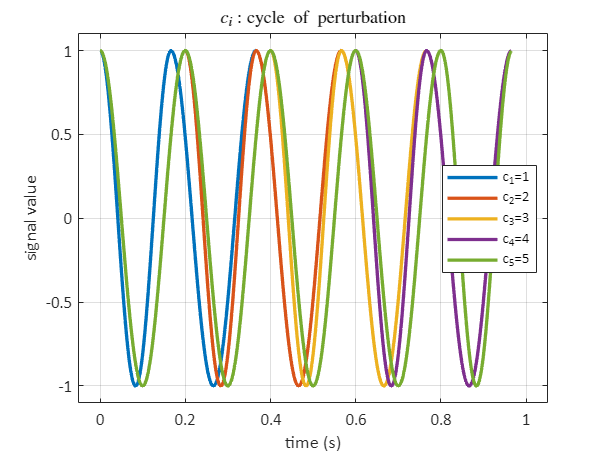

S = test_signals('cos_freq_pert');
ph = plot_signals(S);

DTW and local rate calculation:

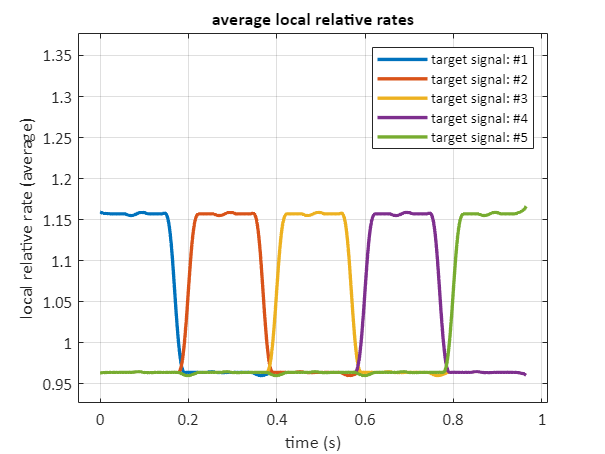

winsize = round(0.05/S.dt); %window size of 0.05 s

for a=1:length(S.X)
    for b=1:length(S.X)
        [wcurves{a,b},dists(a,b),dtwinfo(a,b)] = dtwm(S.X{a},S.X{b});
        loc_rates{a,b} = lrr(wcurves{a,b},'winsize',winsize);
    end
end

plot_average_local_rates(S,loc_rates);
ylim(ylim+[0 0.65*diff(ylim)]);

As can be seen in the average local relative rate, target signal #1 (blue line) is increased relative to the others during its first cycle, signal #2 during its second cycle, and so on. Outside of the time periods in which the frequency perturbations are applied, the local relative rates are slightly below $1.0$, because one of the other signals in the comparison set is sped up during this time.

function [] = fig()
clear all; %#ok<CLALL> 
figure('units','pixels','position',[ 680   558   560   420]);
set(0,'defaultlinelinewidth',2);
end

function [] = format_axes()
set(gca,'XGrid','on','YGrid','on');
xlim(xlim+0.05*diff(xlim)*[-1 1]);
ylim(ylim+0.05*diff(ylim)*[-1 1]);

end

function [ph] = plot_signals(S)
fig;
for i=1:length(S.X)
    ph(i) = plot(S.t{i},S.X{i}); hold on;
end
title(S.formula,'Interpreter','latex');
xlabel('time (s)');
ylabel('signal value');
legend(ph,S.labels,'location','best');
format_axes;
end

function [] = format_plot(setname,varargin)
if nargin>1, S = varargin{1}; end
if nargin>2, ph = varargin{2}; end
switch(setname)
    case 'example_set'
        title(S.formula,'Interpreter','latex');
        legend(ph,S.labels,'location','northeast');
        xlabel('time (s)');
        ylim(ylim+0.05*diff(ylim)*[-1 1]);
        set(gca,'Box','on','ygrid','on');

    case 'example_zoom'
        set(gca,'XGrid','on','YGrid','on','XLim',[0.5 10.5]);
        xlabel('target signal sample index');
        ylabel('comparison signal sample index');
        title('warping map');
        
    case 'many_to_many'
        axis tight;
        xlim(xlim+[-0.5 0.5]);
        ylim(ylim+[-0.5 0.5]);
        set(gca,'XGrid','on','YGrid','on');
        xlabel('sample index');
        ylabel('signal value');

    case 'many_to_many_map'
        set(S.maph,'marker','o');
        stfig_gridlines('xy');
        S.s1.Marker = 'o';
        S.s2.Marker = 's';
        S.xlabs1.String = 'target signal sample index';
        S.ylabs2.String = 'comparison signal sample index';        
end
end

%% slope
function [] = slope_defs(m)
fig; 
plot(m(1,:),m(2,:),'ko-','markersize',4); hold on;
xlabel('sample index (target)');
ylabel('sample index (comparison)'); set(gca,'XGrid','on','YGrid','on');

ix = 5;
m2m1 = @(ix)m(2,find(m(1,:)==ix,1,'first'));

plot(ix-1*[1 1],[0 m2m1(ix-1)],'k--','linew',1);
plot(ix*[1 1],[0 m2m1(ix)],'k-','linew',1);
plot(ix+1*[1 1],[0 m2m1(ix+1)],'k--','linew',1);


backward_diff = @(ix)m2m1(ix)-m2m1(ix-1);
forward_diff = @(ix)m2m1(ix+1)-m2m1(ix);
central_diff = @(ix)(backward_diff(ix)+forward_diff(ix))/2;

y = @(x,intercept,slope)intercept+slope*x;

ixx = ix-3:ix+3;
ph(1) = plot(ixx-1,y(ixx-1,2,backward_diff(ix)),'m:');
ph(2) = plot(ixx+1,y(ixx+1,7,forward_diff(ix)),'b:');
ph(3) = plot(ixx,y(ixx,4.5,central_diff(ix)),'g:');

strs = {'backward','forward','central'};
for i=1:length(ph)
    text(ph(i).XData(end),ph(i).YData(end),strs{i});
end
end

function [] = locality_comparison(m,local_slopes,window_sizes)
fig;
plot(m(1,:),m(2,:),'ko-','markersize',4); hold on;
xlabel('target sample index'); 
ylabel('comparison sample index'); 
axis tight; format_axes;

fig;
for i=1:length(local_slopes)
    ph(i) = plot(local_slopes{i},'o-','markersize',4); hold on;
end
axis tight;
ylim(ylim+0.1*diff(ylim)*[-1 1]);
leg_strs = arrayfun(@(c){sprintf('window size: %i',c)},window_sizes);
legend(ph,leg_strs,'location','best');
xlabel('target sample index');
ylabel('local slope');
axis tight; format_axes;
end

function [] = windows_comparison(local_slopes,windows)
fig;
for i=1:length(local_slopes)
    ph(i) = plot(local_slopes{i},'o-','markersize',4); hold on;
end
axis tight;
ylim(ylim+0.1*diff(ylim)*[-1 1]);
legend(ph,windows,'location','best');
xlabel('target sample index');
ylabel('local slope');
axis tight; format_axes;
end

function [] = plot_toy_example_signals(mm)
fig;
ph(1) = plot(mm.X{1},'o-'); hold on; 
ph(2) = plot(mm.X{2},'s-');
format_plot('many_to_many');
legend(ph,{'target' 'comparison'});
end

function [] = plot_relative_rates(S,loc_rates,signal_num)
fig;
N = size(loc_rates,2);
for i=1:N
    ph(i) = plot(S.t{signal_num},loc_rates{signal_num,i}); hold on;
end
legstrs = arrayfun(@(c){sprintf('rate of %i rel. to %i',signal_num,c)},(1:N));
legend(ph,legstrs,'location','best');
xlabel('time (s)');
ylabel('local relative rate');
title(sprintf('relative rates of signal #%i',signal_num));
format_axes;
end

function [] = plot_average_local_rates(S,loc_rates)
fig;
for i=1:length(loc_rates)
    ph(i) = plot(S.t{i},geomean(cell2mat(loc_rates(i,:)'))); hold on;
end
axis tight;
ylim(ylim+0.1*diff(ylim)*[-1 1]);
legend(ph,arrayfun(@(c){sprintf('target signal: #%i',c)},(1:size(loc_rates,1))))
title('average local relative rates');
ylabel('local relative rate (average)');
xlabel('time (s)');
format_axes;
end

function [] = mapping_legend(hh,labs)

hx(1) = plot(nan,nan,'Marker',hh.lh1(1).Marker,'Color',hh.lh1(1).Color, ...
    'Markersize',hh.lh1(1).MarkerSize,'markerfacecolor',hh.lh1(1).MarkerFaceColor, ...
    'LineStyle','none','LineWidth',1);
hx(2) = plot(nan,nan,'Marker',hh.lh2(1).Marker,'Color',hh.lh2(1).Color, ...
    'Markersize',hh.lh2(1).MarkerSize,'markerfacecolor',hh.lh2(1).MarkerFaceColor,...
    'LineStyle','none','LineWidth',1);

legend(hx,labs,'NumColumns',2);

end